# Question 2

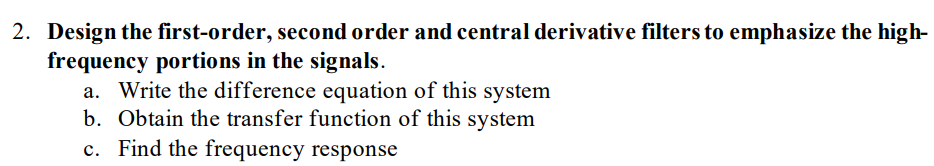

## Part 1

difference equations:

1st order = y[n] = x[n]-x[n-1]

transfer function = 1-z^-1

2nd order = y[n] = (x[n]-x[n-1]) - (x[n-1]-x[n-2])

transfer function = 1- (2*z^-1)+(z^-2)

central derivative = y[n] = (x[n+1]-x[n-1])/2

transfer function =0.5( z^1-z^-1)

## Frequency Responses

syms w
W = 0.01:0.01:pi;

first_order = 1-exp(-1j*w)

$$first\_order = 1-{\mathrm{e}}^{-w\,\mathrm{i}}$$

second_order = 1-2*exp(-1j*w)+exp(-2j*w)

$$second\_order = 1+{\mathrm{e}}^{-2\,w\,\mathrm{i}}-2\,{\mathrm{e}}^{-w\,\mathrm{i}}$$

central = 0.5*(exp(1j*w)-exp(-1j*w))

$$central = -\frac{{\mathrm{e}}^{-w\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{w\,\mathrm{i}}}{2}$$


first_subs = subs(first_order,w,W);
second_subs = subs(second_order,w,W);
central_subs= subs(central,w,W);

## Plots (mag):

subplot(3,1,1)
plot(W,abs(first_subs))
ylabel('H1(w)')
xlabel('w')
title('plot of magnitude of First derivative frequency response')

subplot(3,1,2)
plot(W,abs(second_subs))
ylabel('H2(w)')
xlabel('w')
title('plot of magnitude of second derivative frequency response')

subplot(3,1,3)
plot(W,abs(central_subs))
ylabel('H3(w)')
xlabel('w')
title('plot of magnitude of central derivative frequency response')


## Plot (phase):

subplot(3,1,1)
plot(W,angle(first_subs))
ylabel('H1(w)')
xlabel('w')
title('plot of angle of First derivative frequency response')

subplot(3,1,2)
plot(W,angle(second_subs))
ylabel('H2(w)')
xlabel('w')
title('plot of angle of second derivative frequency response')

subplot(3,1,3)
plot(W,angle(central_subs))
ylabel('H3(w)')
xlabel('w')
title('plot of angle of central derivative frequency response')

## Z transforms

syms z
hz1 =  1-z^(-1)

$$hz1 = 1-\frac{1}{z}$$

hz2 = 1- 2*z^(-1) +z^(-2)

$$hz2 = \frac{1}{z^{2}}-\frac{2}{z}+1$$

hz3 = 0.5*(z^1-z^(-1))

$$hz3 = \frac{z}{2}-\frac{1}{2\,z}$$

## Poles and zeros

first order : poles = 0, zeros = 1

second order : poles = 0, zeros = 1,1

central difference : poles =0,infinity,  zeros=1,-1

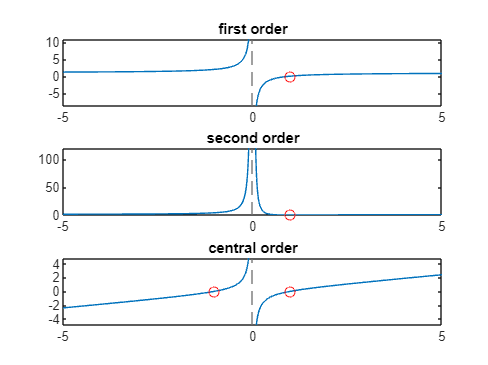

clf
subplot(3,1,1)
fplot(hz1)
title('first order')
hold on;
plot(1, 0, 'ro'); 
hold off;

subplot(3,1,2)
fplot(hz2)
title('second order')
hold on;
plot(1, 0, 'ro'); 
hold off;

subplot(3,1,3)
fplot(hz3)
title('central order')
hold on;
plot(1, 0, 'ro'); 
plot(-1, 0, 'ro'); 
hold off;

## H values

h1 = [1,-1]

h1 =      1    -1


h2 = [1,-2,1]

h2 =      1    -2     1


h3 = [0.5,0,-0.5]

h3 =     0.5000         0   -0.5000


## PPG

ppg_signal = ppg_random;

y1_ppg = conv(h1,ppg_signal);
y2_ppg = conv(h2,ppg_signal);
y3_ppg = conv(h3,ppg_signal);

## Plots

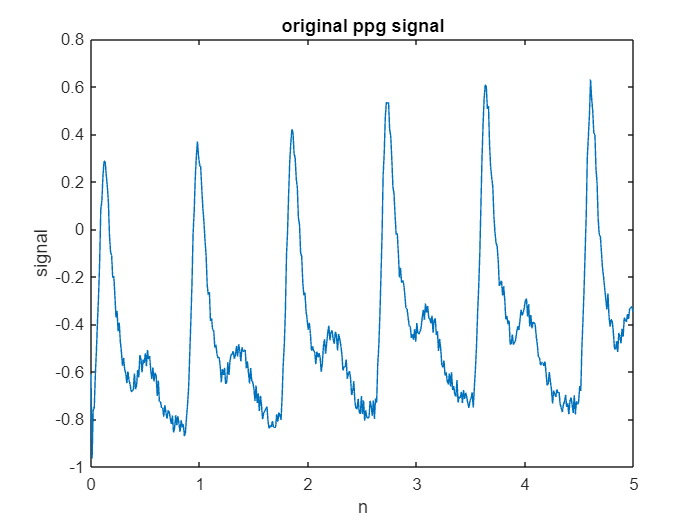

clf
plot(0:0.01:4.99,ppg_signal)
ylabel('signal')
xlabel('n')
title('original ppg signal')

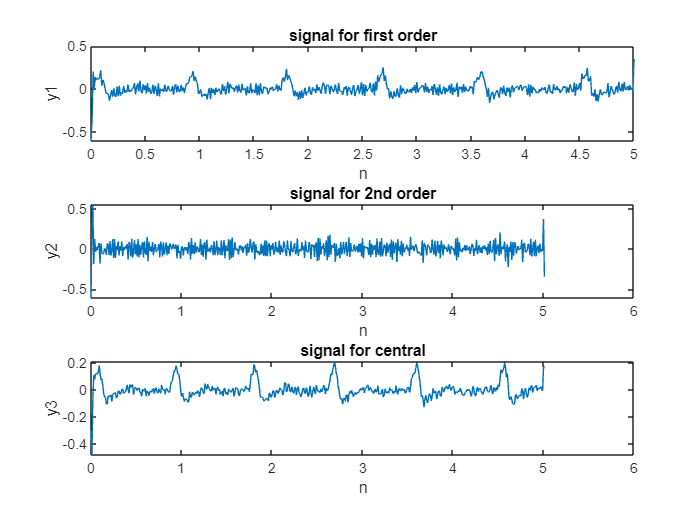

clf
subplot(3,1,1)
d1 = 0:0.01:(length(y1_ppg)-1)/100;
plot(d1,y1_ppg)
ylabel('y1')
xlabel('n')
title('signal for first order')

subplot(3,1,2)
d2 = 0:0.01:(length(y2_ppg)-1)/100;
plot(d2,y2_ppg)
ylabel('y2')
xlabel('n')
title('signal for 2nd order')

subplot(3,1,3)
d3 = 0:0.01:(length(y3_ppg)-1)/100;
plot(d3,y3_ppg)
ylabel('y3')
xlabel('n')
title('signal for central')

## ECG

ecg_signal = ECG_10sec_clean_360

ecg_signal =     0.0022    0.0012    0.0002   -0.0008   -0.0020   -0.0033   -0.0051   -0.0072   -0.0098   -0.0127   -0.0161   -0.0199   -0.0241   -0.0287   -0.0337   -0.0390   -0.0444   -0.0498   -0.0549   -0.0599   -0.0645   -0.0688   -0.0726   -0.0760   -0.0789   -0.0814   -0.0833   -0.0849   -0.0863   -0.0873   -0.0882   -0.0889   -0.0893   -0.0896   -0.0899   -0.0901   -0.0902   -0.0903   -0.0903   -0.0903   -0.0901   -0.0898   -0.0894   -0.0890   -0.0884   -0.0877   -0.0868   -0.0856   -0.0842   -0.0824


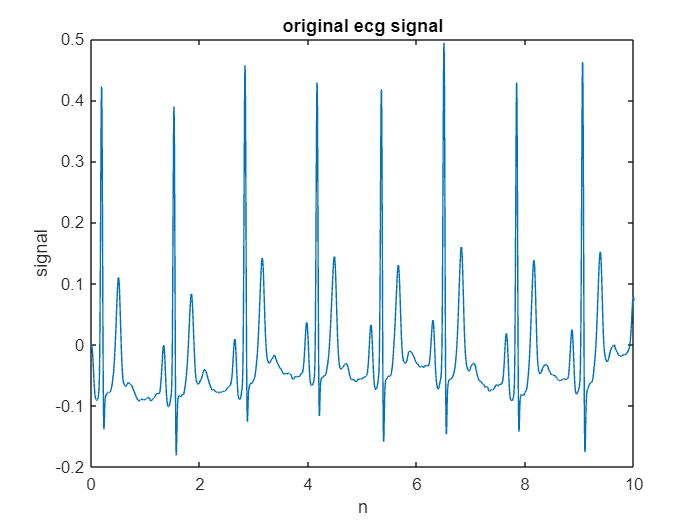


clf
plot(1/360:1/360:10,ecg_signal)
ylabel('signal')
xlabel('n')
title('original ecg signal')

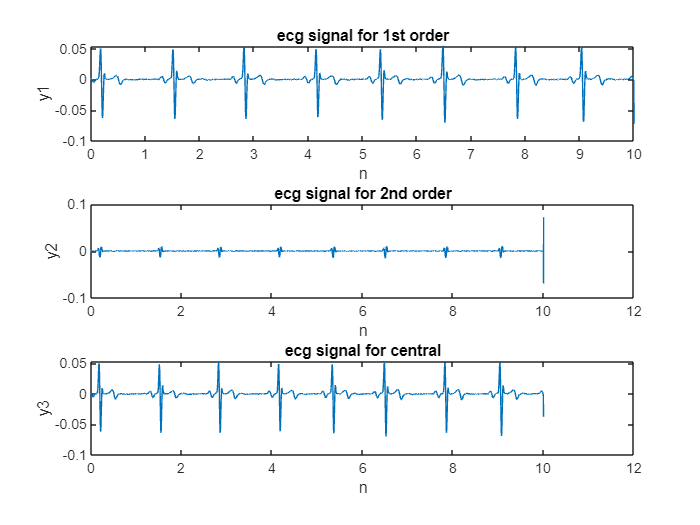

y1_ecg = conv(h1,ecg_signal);
y2_ecg = conv(h2,ecg_signal);
y3_ecg = conv(h3,ecg_signal);

clf
subplot(3,1,1)
db1 = 0:1/360:(length(y1_ecg)-1)/360;
plot(db1,y1_ecg)
ylabel('y1')
xlabel('n')
title('ecg signal for 1st order')

subplot(3,1,2)
db2 = 0:1/360:(length(y2_ecg)-1)/360;
plot(db2,y2_ecg)
ylabel('y2')
xlabel('n')
title('ecg signal for 2nd order')

subplot(3,1,3)
db3 = 0:1/360:(length(y3_ecg)-1)/360;
plot(db3,y3_ecg)
ylabel('y3')
xlabel('n')
title('ecg signal for central')